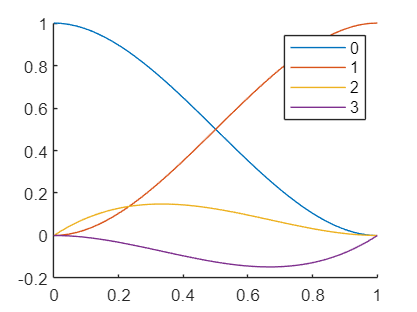

clear; 

syms h u t u0 u1 f0 f1

b0 = getPoly(t, 1, [1,0,0,0]');
b1 = getPoly(t, 1, [0,1,0,0]');
b2 = getPoly(t, 1, [0,0,1,0]');
b3 = getPoly(t, 1, [0,0,0,1]');
figure(1); clf;hold on;
fplot(b0,[0,1])
fplot(b1,[0,1])
fplot(b2,[0,1])
fplot(b3,[0,1])
hold off;
legend('0','1','2','3');

## integration

syms alpha alpha2 v0 v1 v2
bases(t) = [1,t,t^2];
bases2(t) = [1,t,t^2,t^3]; % _2 is for 3rd degree poly integration
weights = int(bases / ([bases(0);bases(alpha); bases(1)]),t,0,1)

$$weights = \left(\begin{array}{ccc} \frac{1}{2}-\frac{1}{6\,\alpha } & -\frac{1}{6\,\alpha \,\left(\alpha -1\right)} & \frac{1}{6\,\left(\alpha -1\right)}+\frac{1}{2} \end{array}\right)$$

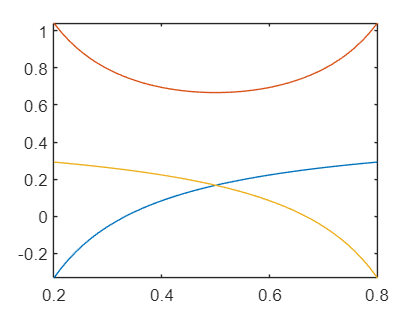

fplot(weights, [0.2,0.8])

weights2 = int(bases2 / ([bases2(0);bases2(alpha);bases2(alpha2); bases2(1)]),t,0,1)

$$weights2 = \begin{array}{l} \left(\begin{array}{cccc} \frac{\frac{\alpha }{2}-\frac{1}{6}}{\alpha }-\frac{\sigma_{1}}{\alpha \,\alpha_{2}} & \frac{2\,\alpha_{2}-1}{12\,\alpha \,\left(\alpha -\alpha_{2}\right)\,\left(\alpha -1\right)} & -\frac{2\,\alpha -1}{12\,\alpha_{2}\,\left(\alpha -\alpha_{2}\right)\,\left(\alpha_{2}-1\right)} & \frac{\frac{\alpha }{2}-\frac{1}{3}}{\alpha -1}+\frac{\sigma_{1}}{\left(\alpha -1\right)\,\left(\alpha_{2}-1\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\alpha }{6}-\frac{1}{12} \end{array}$$

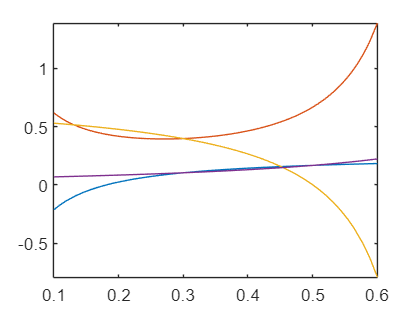

fplot(subs(weights2,alpha2,0.7), [0.1,0.6])

## input

u_mid = [b0(alpha),b1(alpha),b2(alpha)*h,b3(alpha)*h] * transpose([u0,u1,f0,f1])

$$u\_mid = u_{0}\,\left(2\,\alpha^{3}-3\,\alpha^{2}+1\right)+u_{1}\,\left(3\,\alpha^{2}-2\,\alpha^{3}\right)-f_{1}\,h\,\left(\alpha^{2}-\alpha^{3}\right)+f_{0}\,h\,\left(\alpha^{3}-2\,\alpha^{2}+\alpha \right)$$

u_mid2 = [b0(alpha2),b1(alpha2),b2(alpha2)*h,b3(alpha2)*h] * transpose([u0,u1,f0,f1])

$$u\_mid2 = u_{0}\,\left(2\,{\alpha_{2}}^{3}-3\,{\alpha_{2}}^{2}+1\right)+u_{1}\,\left(3\,{\alpha_{2}}^{2}-2\,{\alpha_{2}}^{3}\right)-f_{1}\,h\,\left({\alpha_{2}}^{2}-{\alpha_{2}}^{3}\right)+f_{0}\,h\,\left({\alpha_{2}}^{3}-2\,{\alpha_{2}}^{2}+\alpha_{2}\right)$$

syms f_mid f_mid2;
incre = weights * [f0; f_mid; f1] * h;
incre2 = weights2 * [f0; f_mid; f_mid2; f1] * h;

% for use:
coefsN = [b0(alpha),b1(alpha),b2(alpha),b3(alpha)]

$$coefsN = \left(\begin{array}{cccc} 2\,\alpha^{3}-3\,\alpha^{2}+1 & 3\,\alpha^{2}-2\,\alpha^{3} & \alpha^{3}-2\,\alpha^{2}+\alpha & \alpha^{3}-\alpha^{2} \end{array}\right)$$

v = simplify(subs(coefsN,(3-sqrt(sym(3)))/6))

$$v = \left(\begin{array}{cccc} \frac{2\,\sqrt{3}}{9}+\frac{1}{2} & \frac{1}{2}-\frac{2\,\sqrt{3}}{9} & \frac{\sqrt{3}}{36}+\frac{1}{12} & \frac{\sqrt{3}}{36}-\frac{1}{12} \end{array}\right)$$

v(1)

$$ans = \frac{2\,\sqrt{3}}{9}+\frac{1}{2}$$

1- v(1)

$$ans = \frac{1}{2}-\frac{2\,\sqrt{3}}{9}$$

v(1)/2  - (2 + sqrt(sym(3)))/12

$$ans = \frac{\sqrt{3}}{36}+\frac{1}{12}$$

## linear stability

syms lambda kappa
u_mid_lam = subs(u_mid, [f0,f1],[u0,u1] * lambda);
u_mid2_lam = subs(u_mid2, [f0,f1],[u0,u1] * lambda);

incre_lam = collect(subs(expand(incre), [f0,f_mid,f1], [u0*lambda,u_mid_lam*lambda,u1*lambda]), [u0,u1])

$$incre\_lam = \begin{array}{l} \left(\frac{h\,\lambda }{2}-\frac{h\,\lambda }{6\,\alpha }+\frac{h\,\lambda \,\left(-3\,\alpha^{2}+2\,\alpha^{3}+h\,\lambda \,\left(\alpha^{3}-2\,\alpha^{2}+\alpha \right)+1\right)}{\sigma_{1}}\right)\,u_{0}+\left(\frac{h\,\lambda }{2}+\frac{h\,\lambda }{6\,\left(\alpha -1\right)}-\frac{h\,\lambda \,\left(2\,\alpha^{3}-3\,\alpha^{2}+h\,\lambda \,\left(\alpha^{2}-\alpha^{3}\right)\right)}{\sigma_{1}}\right)\,u_{1}\\ \mathrm{where}\\ \sigma_{1}=\left(\alpha -\alpha^{2}\right)\,6 \end{array}$$

K = subs(simplify(solve(incre_lam + (u0 - u1), u1 )/u0), h*lambda, kappa)

$$K = -\frac{4\,\kappa -2\,\alpha \,\kappa -\alpha \,\kappa^{2}+\kappa^{2}+6}{2\,\kappa +2\,\alpha \,\kappa -\alpha \,\kappa^{2}-6}$$

syms c_2 z
latex(subs(K,[kappa,alpha],[z,c_2]))

ans = '-\frac{4\,z-2\,c_{2}\,z-c_{2}\,z^2+z^2+6}{2\,z+2\,c_{2}\,z-c_{2}\,z^2-6}'

incre2_lam = collect(subs(expand(incre2), [f0,f_mid, f_mid2,f1], [u0,u_mid_lam, u_mid2_lam,u1]*lambda), [u0,u1])

$$incre2\_lam = \begin{array}{l} \left(\frac{h\,\lambda }{2}-\frac{h\,\lambda }{6\,\alpha }-\frac{h\,\lambda }{6\,\alpha_{2}}+\frac{h\,\lambda }{12\,\alpha \,\alpha_{2}}-\frac{h\,\lambda \,\sigma_{2}}{\sigma_{6}\,12}-\frac{h\,\lambda \,\sigma_{1}}{\sigma_{5}\,12}+\frac{\alpha_{2}\,h\,\lambda \,\sigma_{2}}{\sigma_{6}\,6}+\frac{\alpha \,h\,\lambda \,\sigma_{1}}{\sigma_{5}\,6}\right)\,u_{0}+\left(-\frac{h\,\lambda }{3\,\left(\alpha -1\right)}+\frac{h\,\lambda }{12\,\sigma_{7}}-\frac{\alpha \,h\,\lambda }{6\,\sigma_{7}}+\frac{h\,\lambda \,\sigma_{3}}{\sigma_{6}\,12}+\frac{h\,\lambda \,\sigma_{4}}{\sigma_{5}\,12}+\frac{\alpha \,h\,\lambda }{2\,\left(\alpha -1\right)}-\frac{\alpha_{2}\,h\,\lambda \,\sigma_{3}}{\sigma_{6}\,6}-\frac{\alpha \,h\,\lambda \,\sigma_{4}}{\sigma_{5}\,6}\right)\,u_{1}\\ \mathrm{where}\\ \sigma_{1}=-3\,{\alpha_{2}}^{2}+2\,{\alpha_{2}}^{3}+h\,\lambda \,\left({\alpha_{2}}^{3}-2\,{\alpha_{2}}^{2}+\alpha_{2}\right)+1\\ \sigma_{2}=-3\,\alpha^{2}+2\,\alpha^{3}+h\,\lambda \,\left(\alpha^{3}-2\,\alpha^{2}+\alpha \right)+1\\ \sigma_{3}=2\,\alpha^{3}-3\,\alpha^{2}+h\,\lambda \,\left(\alpha^{2}-\alpha^{3}\right)\\ \sigma_{4}=2\,{\alpha_{2}}^{3}-3\,{\alpha_{2}}^{2}+h\,\lambda \,\left({\alpha_{2}}^{2}-{\alpha_{2}}^{3}\right)\\ \sigma_{5}=\alpha \,\alpha_{2}-\alpha \,{\alpha_{2}}^{2}-{\alpha_{2}}^{2}+{\alpha_{2}}^{3}\\ \sigma_{6}=\alpha \,\alpha_{2}-\alpha^{2}\,\alpha_{2}-\alpha^{2}+\alpha^{3}\\ \sigma_{7}=\alpha +\alpha_{2}-\alpha \,\alpha_{2}-1 \end{array}$$

K2 = subs(simplify(solve(incre2_lam + (u0 - u1), u1 )/u0), h*lambda, kappa)

$$K2 = \frac{\kappa^{2}+6\,\kappa +12}{\kappa^{2}-6\,\kappa +12}$$


syms a b
assume([a,b,alpha], 'real')
[KN, KD] = numden(K);
KC = simplify(expand(...
    subs(K, kappa, a * (cos(b) + 1i*sin(b)))*...
    conj(subs(K, kappa, a * (cos(b) + 1i*sin(b))))...
    ))

$$KC = \begin{array}{l} -\frac{\sigma_{5}-2\,a^{4}\,\alpha +a^{4}+\sigma_{2}-12\,a^{3}\,\alpha \,\cos\left(b\right)+8\,a^{3}\,\cos\left(b\right)+\sigma_{3}-\sigma_{1}-\sigma_{6}+24\,a^{2}\,{\cos\left(b\right)}^{2}+4\,a^{2}-\sigma_{4}+48\,a\,\cos\left(b\right)+36}{-\sigma_{5}+\sigma_{2}+4\,a^{3}\,\alpha \,\cos\left(b\right)-\sigma_{3}-\sigma_{1}+\sigma_{6}-4\,a^{2}+\sigma_{4}+24\,a\,\cos\left(b\right)-36}\\ \mathrm{where}\\ \sigma_{1}=24\,a^{2}\,\alpha \,{\cos\left(b\right)}^{2}\\ \sigma_{2}=4\,a^{3}\,\alpha^{2}\,\cos\left(b\right)\\ \sigma_{3}=4\,a^{2}\,\alpha^{2}\\ \sigma_{4}=24\,a\,\alpha \,\cos\left(b\right)\\ \sigma_{5}=a^{4}\,\alpha^{2}\\ \sigma_{6}=4\,a^{2}\,\alpha \end{array}$$

collect(KC, cos(b))

$$ans = \begin{array}{l} \frac{\left(24\,a^{2}-\sigma_{4}\right)\,{\cos\left(b\right)}^{2}+\left(\sigma_{1}-12\,a^{3}\,\alpha +8\,a^{3}-24\,a\,\alpha +48\,a\right)\,\cos\left(b\right)+\sigma_{3}-2\,a^{4}\,\alpha +a^{4}+\sigma_{2}-\sigma_{5}+4\,a^{2}+36}{\sigma_{4}\,{\cos\left(b\right)}^{2}+\left(-\sigma_{1}-4\,a^{3}\,\alpha -24\,a\,\alpha -24\,a\right)\,\cos\left(b\right)+\sigma_{3}+\sigma_{2}-\sigma_{5}+4\,a^{2}+36}\\ \mathrm{where}\\ \sigma_{1}=4\,a^{3}\,\alpha^{2}\\ \sigma_{2}=4\,a^{2}\,\alpha^{2}\\ \sigma_{3}=a^{4}\,\alpha^{2}\\ \sigma_{4}=24\,a^{2}\,\alpha \\ \sigma_{5}=4\,a^{2}\,\alpha \end{array}$$

## stablility region

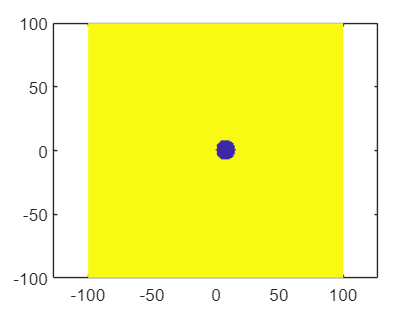

test_range = 100;
rSamp = linspace(-test_range,test_range,201);
iSamp = linspace(-test_range,test_range,201);
[rSampM,iSampM] = meshgrid(rSamp,iSamp);
zSampM = rSampM + 1i * iSampM;
Kf = matlabFunction(symfun(K, [kappa, alpha]));
Kf2 = matlabFunction(symfun(K2, [kappa, alpha, alpha2]));
alphatest = 0.7;
% alphatest = 2/3;
KM = abs(Kf(zSampM, alphatest));
KM2 = abs(Kf2(zSampM, alphatest, 1 - alphatest));

p = pcolor(rSampM,iSampM, double(KM < 1));
p.EdgeColor = 'none';
axis equal;

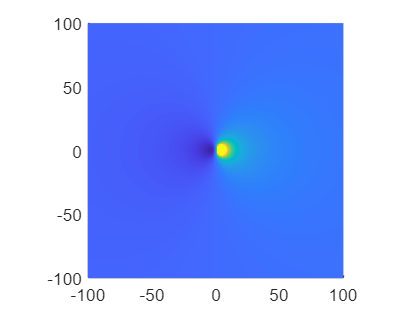


s = surf(rSampM,iSampM, double(min(KM,2)));
s.EdgeColor = 'none';
axis equal;
view(0,90)

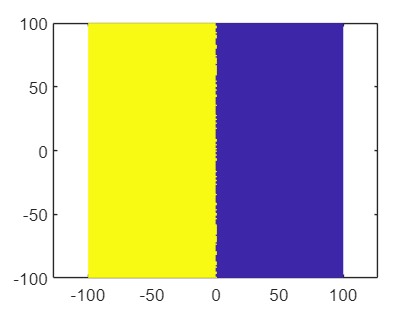


p = pcolor(rSampM,iSampM, double(KM2 < 1));
p.EdgeColor = 'none';
axis equal;

## jacobian

syms J J_m idt
c = sym("c",[4,1]);
w = sym("w",[3,1]);
JA = w(3) * J + w(2) * J_m * (J * c(4) * h + c(2)) - 1/h

$$JA = J\,w_{3}-\frac{1}{h}+J_{m}\,w_{2}\,\left(c_{2}+J\,c_{4}\,h\right)$$

JA1 = c(4)*w(2) * (J + c(2)/c(4)/h) * (J_m + w(3)/(c(4)*h * w(2))) * h

$$JA1 = c_{4}\,h\,w_{2}\,\left(J_{m}+\frac{w_{3}}{c_{4}\,h\,w_{2}}\right)\,\left(J+\frac{c_{2}}{c_{4}\,h}\right)$$

simplify(expand(JA1))

$$ans = \frac{\left(c_{2}+J\,c_{4}\,h\right)\,\left(w_{3}+J_{m}\,c_{4}\,h\,w_{2}\right)}{c_{4}\,h}$$

expand(JA - JA1)

$$ans = -\frac{1}{h}-\frac{c_{2}\,w_{3}}{c_{4}\,h}$$

simplify(subs(expand(JA - JA1), [c;w],[transpose(coefsN); transpose(weights)]) * h)

$$ans = -\frac{\alpha }{6\,{\left(\alpha -1\right)}^{2}}$$

subs((JA), [c;w],[transpose(subs(coefsN,alpha,1/2)); transpose(subs(weights,alpha,1/2))])

$$ans = \frac{J}{6}-\frac{2\,J_{m}\,\left(\frac{J\,h}{8}-\frac{1}{2}\right)}{3}-\frac{1}{h}$$

## jacobian 2

syms J1 Jm h CFL
Jorig = [w(3) * J1 - 1/h, w(2) * Jm; c(2)/h + c(4) * J1, -1/h]

$$Jorig = \left(\begin{array}{cc} J_{1}\,w_{3}-\frac{1}{h} & \mathrm{Jm}\,w_{2}\\ J_{1}\,c_{4}+\frac{c_{2}}{h} & -\frac{1}{h} \end{array}\right)$$

syms theta
rowT = [1 0; theta, 1];
% rowT = inv([w(3), w(2); c(4), 0])
swapRow = [0,1;1,0];
Jtheta = swapRow * rowT * Jorig * swapRow';
Jtheta0 = simplify(expand(Jtheta))

$$Jtheta0 = \left(\begin{array}{cc} \mathrm{Jm}\,\theta \,w_{2}-\frac{1}{h} & \frac{c_{2}-\theta +J_{1}\,c_{4}\,h+J_{1}\,h\,\theta \,w_{3}}{h}\\ \mathrm{Jm}\,w_{2} & J_{1}\,w_{3}-\frac{1}{h} \end{array}\right)$$

Jtheta = subs(Jtheta, [c;w], [transpose(coefsN); transpose(weights)]);
JthetaCh = subs(Jtheta, [J1,Jm], [-CFL/h, -CFL/h]) * h;
JthetaCh = simplify(expand(JthetaCh));
alphaSamp = 1/2;
% thetaSamp = -coefsN(4)/weights(3);
thetaSamp = 32/8;
% alphaSamp = alpha;
% thetaSamp = theta;
JJ = simplify(subs(JthetaCh,[theta,alpha],...
    [thetaSamp,alphaSamp]));
JJ = simplify(subs(JJ,[theta,alpha],...
    [thetaSamp,alphaSamp]));
rhoJJ = -JJ(2,1) * JJ(1,2) / JJ(2,2) / JJ(1,1)

$$rhoJJ = \frac{6\,\mathrm{CFL}\,\left(\alpha -1\right)\,\left(\theta +\frac{\mathrm{CFL}\,\theta }{2}-\mathrm{CFL}\,\alpha^{2}+\mathrm{CFL}\,\alpha^{3}-3\,\alpha^{2}+2\,\alpha^{3}-\frac{\mathrm{CFL}\,h\,\theta }{6\,\left(h-\alpha \,h\right)}\right)}{\left(-6\,\alpha^{2}+6\,\alpha +\mathrm{CFL}\,\theta \right)\,\left(2\,\mathrm{CFL}-6\,\alpha -3\,\mathrm{CFL}\,\alpha +6\right)}$$


simplify(limit(rhoJJ, CFL, inf))

$$ans = -\frac{6\,\alpha^{4}-12\,\alpha^{3}+6\,\alpha^{2}+3\,\theta \,\alpha -2\,\theta }{\theta \,\left(3\,\alpha -2\right)}$$


% thetaExtre = solve(diff(rhoJJ, CFL)==0, CFL)
% thetaExtreF = symfun(thetaExtre, theta);
% fplot(thetaExtreF)
% xlabel("\theta")

figure(2)
fplot(symfun((rhoJJ),CFL),[0,200])
xlim([-1,20])
ylim([-1,1])

## jacobian2 num find

figure(1); clf; hold on;
alphaSamps = [0.5,0.55,0.6];
lines = ["-o", "-x", "-d"]

lines = 1×3 string array
    "-o"    "-x"    "-d"


for  i = 1:3
    alphaSamp = alphaSamps(i);
% thetaSamp = -coefsN(4)/weights(3);
thetaSamp = theta;
JJ = simplify(subs(JthetaCh,[theta,alpha],...
    [thetaSamp,alphaSamp]));
JJ = simplify(subs(JJ,[theta,alpha],...
    [thetaSamp,alphaSamp]));
rhoJJ = -JJ(2,1) * JJ(1,2) / JJ(2,2) / JJ(1,1)
fRho = matlabFunction(symfun(abs(rhoJJ),[CFL, theta]));

CFLTestsR = [linspace(0,20,201), logspace(21,1e4,101)];
CFLTestsR(1) = 1e-3;
CFLTestsI = CFLTestsR;
% CFLTestsI = [CFLTestsI, -CFLTestsI];

CFLTests = CFLTestsR + 1i * CFLTestsI';
CFLTests = CFLTests(:)';

thetaTests = linspace(0,2,501);
rhoTests = fRho(CFLTests, thetaTests');
rhoMTests = max(rhoTests,[],2);
plot(thetaTests,rhoMTests, lines(i), "DisplayName", sprintf("$c_2 = %g$", alphaSamp), "MarkerIndices",1:20:numel(thetaTests));
ylim([0,2])
[minR, iminR] = min(rhoMTests,[],'all')
thetaM = thetaTests(iminR)
end

$$rhoJJ = \frac{2\,\mathrm{CFL}\,\left(\frac{\mathrm{CFL}}{8}-\theta -\frac{\mathrm{CFL}\,\theta }{6}+\frac{1}{2}\right)}{3\,\left(\frac{\mathrm{CFL}}{6}+1\right)\,\left(\frac{2\,\mathrm{CFL}\,\theta }{3}+1\right)}$$

minR = 0.1831

iminR = 162

thetaM = 0.6440

$$rhoJJ = \frac{200\,\mathrm{CFL}\,\left(\frac{1089\,\mathrm{CFL}}{8000}-\theta -\frac{7\,\mathrm{CFL}\,\theta }{54}+\frac{2299}{4000}\right)}{297\,\left(\frac{7\,\mathrm{CFL}}{54}+1\right)\,\left(\frac{200\,\mathrm{CFL}\,\theta }{297}+1\right)}$$

minR = 0.2802

iminR = 209

thetaM = 0.8320

$$rhoJJ = \frac{25\,\mathrm{CFL}\,\left(\frac{18\,\mathrm{CFL}}{125}-\theta -\frac{\mathrm{CFL}\,\theta }{12}+\frac{81}{125}\right)}{36\,\left(\frac{\mathrm{CFL}}{12}+1\right)\,\left(\frac{25\,\mathrm{CFL}\,\theta }{36}+1\right)}$$

minR = 0.4488

iminR = 302

thetaM = 1.2040

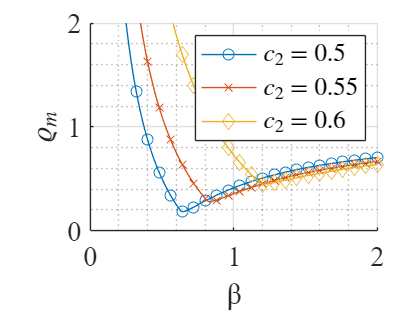

grid on ; grid minor;
legend("Interpreter","latex");
xlabel("\beta");
ylabel("$\varrho_m$","Interpreter","latex")
set(gca,"FontName","Times New Roman")
set(gca,"FontSize", 15)

## Jacobian 3

% factorization, gammaF(I + alphaF dt Jm) (I + betaF dt J1) + muF 
gammaF = -coefsN(2) * weights(3) / coefsN(4);
alphaF =  coefsN(4) * weights(2) / weights(3);
betaF =   coefsN(4) / coefsN(2);
muF = (coefsN(4) + coefsN(2) * weights(3))/coefsN(4);
syms TI JL;
FCT = (gammaF * TI *(1 + alphaF * JL) - muF)/ (gammaF * (1 + alphaF * JL)*(1 + betaF * JL + TI));
FCT = subs(subs(FCT, TI, -JL*1000),alpha,1/2)

$$FCT = \frac{3\,\left(\frac{2000\,\mathrm{JL}\,\left(\frac{\mathrm{JL}}{2}-1\right)}{3}-\frac{1}{3}\right)}{2\,\left(\frac{\mathrm{JL}}{2}-1\right)\,\left(\frac{4001\,\mathrm{JL}}{4}-1\right)}$$

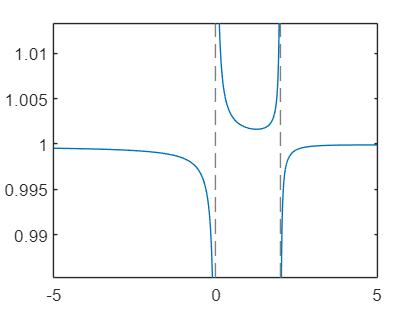

 fplot(symfun(FCT, JL))

## Butcher

cbut = transpose([0,alpha,1])

$$cbut = \left(\begin{array}{c} 0\\ \alpha \\ 1 \end{array}\right)$$

bbut = weights

$$bbut = \left(\begin{array}{ccc} \frac{1}{2}-\frac{1}{6\,\alpha } & -\frac{1}{6\,\alpha \,\left(\alpha -1\right)} & \frac{1}{6\,\left(\alpha -1\right)}+\frac{1}{2} \end{array}\right)$$

abut = [0,0,0; coefsN(3) + coefsN(2) * weights(1), coefsN(2) * weights(2), coefsN(4) + coefsN(2) * weights(3); bbut];
abut = simplify(expand(abut))

$$abut = \left(\begin{array}{ccc} 0 & 0 & 0\\ -\frac{\alpha \,\left(\alpha -3\right)}{6} & \frac{\alpha \,\left(2\,\alpha -3\right)}{6\,\left(\alpha -1\right)} & \frac{\alpha^{3}}{6\,\left(\alpha -1\right)}\\ \frac{1}{2}-\frac{1}{6\,\alpha } & -\frac{1}{6\,\alpha \,\left(\alpha -1\right)} & \frac{1}{6\,\left(\alpha -1\right)}+\frac{1}{2} \end{array}\right)$$

syms k 
fSimpC(k) = abut * cbut.^(k-1) - cbut.^k / k;
simplify(expand(fSimpC(4)))

$$ans = \left(\begin{array}{c} 0\\ \frac{\alpha^{3}\,\left(\alpha -2\right)}{12}\\ \frac{1}{12}-\frac{\alpha }{6} \end{array}\right)$$

predI = inv(abut(2:3,2:3))

$$predI = \left(\begin{array}{cc} \frac{3\,\alpha -2}{\alpha \,\left(\alpha -1\right)} & -\frac{\alpha^{2}}{\alpha -1}\\ \frac{1}{\alpha^{2}\,\left(\alpha -1\right)} & \frac{2\,\alpha -3}{\alpha -1} \end{array}\right)$$

function po = getPoly(t, h, cond)
    bases(t) = [1,t,t^2,t^3];
    dB(t) = diff(bases,t);
    valBases = [bases(0); bases(h);...
        dB(0); dB(h)];
    coefs = valBases \ cond;
    po = bases * coefs;
end




